clc
clear

disp("Initilization Procedure")

Initilization Procedure


model.Parameters

param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]


param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


simtime = 10*60;

% param.model.Dg*param.ctrl.Lambda_Bar

% Skriver en diagonal -1 på integralstaten.
% for i=1:4
%     param.model.A(3*i,3*i) = -1
% end

## Control

[param.ctrl.Ks res] = control.DesignProcedure1(param,0); 

sol = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '23.2.0.2409890 (R2023b) Update 3'
       yalmiptime: 0.0739
       solvertime: 0.0031
             info: 'Successfully solved (MOSEK-SDP)'
          problem: 0


LPV
eig LPV


ans = 1.0e+03 *

   -0.0010
   -0.0010
   -0.0010
   -0.0010
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000


Evaluation of design procedure 1 
cali_Q is positive definite


ans =     0.3021    0.3034    0.3034    0.3034    0.7871    0.7871    0.7871    0.7884    2.0153    2.0153    2.0153    2.0161


cali_R is positive definite


ans = 1.0e-10 *

    0.0007    0.0008    0.0008    0.0008    0.0035    0.0037    0.0040    0.0042    0.1596    0.1922    0.2206    0.2283


Tau is found to be:


ans = -4.5351e-19

Eigenvalues of the decoupled systems are all negative 


ans =   -1.2382 + 4.0460i  -1.2382 - 4.0460i  -0.2810 + 0.0000i  -1.2415 + 4.0904i  -1.2415 - 4.0904i  -0.2806 + 0.0000i  -1.2382 + 4.0460i  -1.2382 - 4.0460i  -0.2810 + 0.0000i  -1.2382 + 4.0460i  -1.2382 - 4.0460i  -0.2810 + 0.0000i


Eigenvalues of the coupled systems are all negative 


ans =   -0.7633 + 5.6104i  -0.7633 - 5.6104i  -0.4591 + 6.3840i  -0.4591 - 6.3840i  -0.3645 + 6.6218i  -0.3645 - 6.6218i  -0.3397 + 6.6635i  -0.3397 - 6.6635i  -0.2748 + 0.0000i  -0.2731 + 0.0000i  -0.2726 + 0.0000i  -0.2727 + 0.0000i


eigenvalues of A


ans =          0
         0
         0
         0
   -4.0442
   -0.0312
   -0.0311
   -4.0059
   -0.0311
   -4.0059


eigenvlaues of Bk


ans =     2.2429
    2.8461
    3.0608
    3.0902
         0
         0
         0
         0
         0
         0


res = 0

% param.ctrl.Ks = control.DesignProcedure2(param,0);

%param.ctrl.Ks = control.DesignProcedureDScalingDiag(param,0);
%param.ctrl.Ks = control.DesignProcedureFunky(param,0);
%param.ctrl.Ks = control.DesignRobust(param,0);

K = blkdiag(param.ctrl.Ks(:,:,1),param.ctrl.Ks(:,:,2),param.ctrl.Ks(:,:,3),param.ctrl.Ks(:,:,4));

## Structured uncertainties

s = tf('s');

w = 1;


An = [param.model.A+param.model.B*K*eye(12)];

M = w*eye(4)*K*eye(12)/(s*eye(12) - (param.model.A+param.model.B*K*eye(12)))*param.model.B + zeros(4);
hinfnorm(M)

ans = 14.5179


W = logspace(-1,3,400);
SV = sigma(M, W)

SV =     1.0049    1.0051    1.0053    1.0056    1.0058    1.0060    1.0063    1.0065    1.0068    1.0071    1.0073    1.0076    1.0079    1.0082    1.0086    1.0089    1.0092    1.0096    1.0099    1.0103    1.0107    1.0111    1.0115    1.0119    1.0123    1.0127    1.0131    1.0136    1.0141    1.0145    1.0150    1.0155    1.0160    1.0165    1.0170    1.0175    1.0180    1.0186    1.0191    1.0197    1.0203    1.0208    1.0214    1.0220    1.0226    1.0232    1.0238    1.0244    1.0250    1.0257
    1.0039    1.0040    1.0042    1.0044    1.0046    1.0047    1.0049    1.0051    1.0053    1.0056    1.0058    1.0060    1.0062    1.0065    1.0067    1.0070    1.0073    1.0075    1.0078    1.0081    1.0084    1.0087    1.0090    1.0093    1.0097    1.0100    1.0103    1.0107    1.0111    1.0114    1.0118    1.0122    1.0126    1.0130    1.0134    1.0138    1.0142    1.0146    1.0150    1.0155    1.0159    1.0164    1.0168    1.0173    1.0177    1.0182    1.0187    1.0192    1.0196    

spectral = zeros(1,length(W));
Ms = freqresp(M,W);
for i=1:length(W)
    spectral(i) = abs(eigs(Ms(:,:,i),1));
end

[bounds,muinfo]  = mussv(frd(M,W),[4,0],'an');

Points completed: 400/400


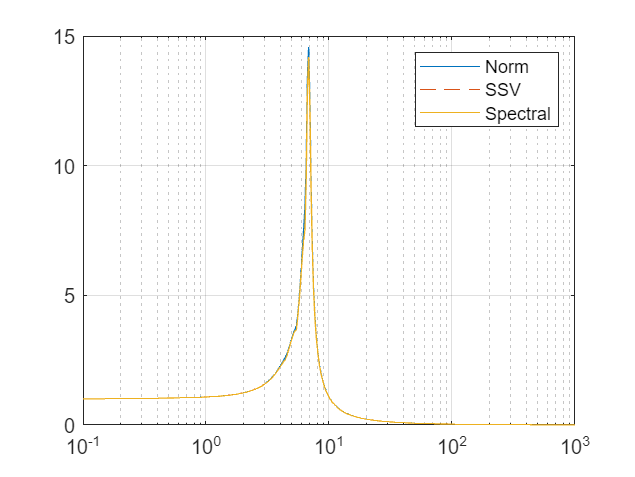


[VDelta,VSigma,VLmi] = mussvextract(muinfo);
VDelta.responsedata(:,:,:);
upperBound = bounds(1).ResponseData(:);

figure()
semilogx(W,max(SV),W,upperBound,'--',W,spectral)
% ylim([0;4])
legend('Norm', 'SSV', 'Spectral')
grid on

set(gcf, 'PaperUnits', 'centimeters');
set(gcf, 'PaperPosition', [0 0 16 9]);
% saveas(gcf,'../Images/SSV_PLOT_Procedure2','epsc')

% H = [An, B*B'; -(K*eye(12))'*(K*eye(12)), -An']

% W = logspace(-1,3,100);
% Ms = freqresp(Mn2,W);
% yalmip('clear')
% gamma = 0.01;
% % D = sdpvar(4,4,'symmetric','complex');
% % Q = D*D'
% D = sdpvar(4,4,'toeplitz','complex');
% Q = D-diag(imag(diag(D)))*sqrt(-1)
% constraints = [Ms(40)*Q*Ms(40)' <= gamma^2*Q, Q>=0]
% options = sdpsettings('verbose',0,'solver','mosek');
% sol = optimize(constraints,[],options)
% value(Q)
% eig(value(Q))


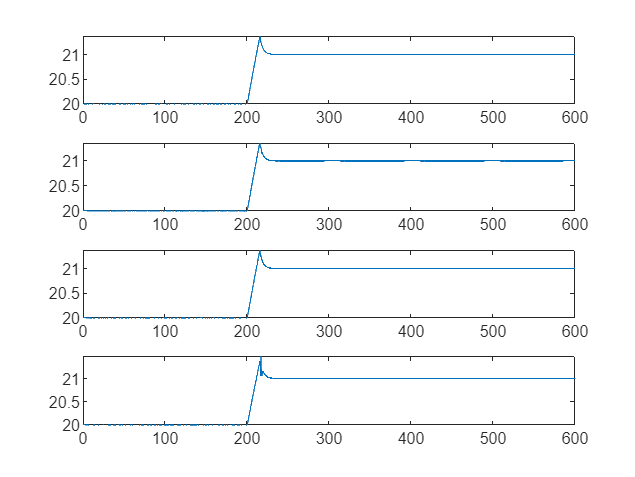

for i=1:4
    x0 = [param.ctrl.T_wOP(i); param.ctrl.T_aOP(i); 0];
    [t,x] = ode45(@(t,x)model.decoupledDynamics(t,x,i,param,200),[0 simtime],x0);
    decoupledResults(i).time = t;
    decoupledResults(i).Tw = x(:,1);
    decoupledResults(i).Ta = x(:,2);
    decoupledResults(i).T = x(:,3);
end
figure()
tiledlayout('vertical')
for i=1:4
    nexttile
    plot(decoupledResults(i).time,decoupledResults(i).Ta-273.15)
end

x0 = [param.ctrl.T_wOP.'; param.ctrl.T_aOP.'; zeros(4,1)];
options = odeset('RelTol',1e-8,'AbsTol',1e-10);
[t,x] = ode45(@(t,x)model.coupledDynamics(t,x,param,200),[0 simtime],x0,options);

coupledResults.time = t;
coupledResults.Tw = x(:,1:4);
coupledResults.Ta = x(:,5:8);
coupledResults.T = x(:,9:12);

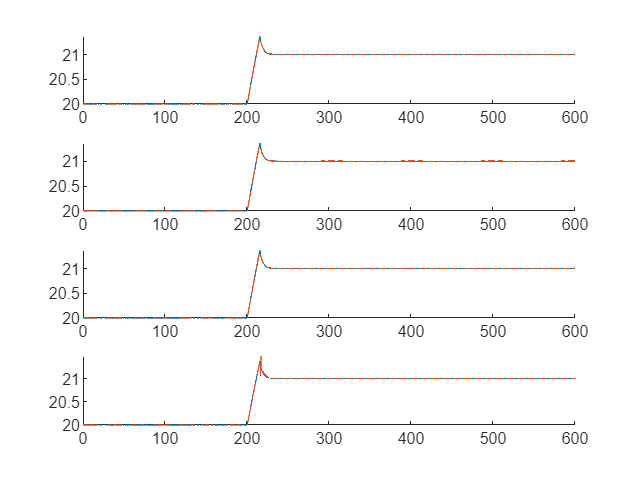


figure()
tiledlayout('vertical')
for i=1:4
    nexttile
    hold on
    plot(coupledResults.time,coupledResults.Ta(:,1)-273.15)
    plot(decoupledResults(i).time,decoupledResults(i).Ta-273.15,'--')
    hold off
end